# DifferentialEquations2dMotion

 This script builds on DifferentialEquations.mlx to solve for ballistic motions in 2 dimensions with linear drag and compares a numerical solution with the [Euler method](https://en.wikipedia.org/wiki/Euler_method) to the exact solution and also the [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) solution.

Author: Duncan Carlsmith

## Euler method of integration

Suppose again we have a  falling mass m subject to uniform gravity and a drag force with the form $f_{drag} = -bv$ where $v$ is the vector velocity and $b$ is some air and mass-shape dependent constant.  Newton's 2nd law has the form

 $ma= F => m dv/dt= mg-bv$ or 


$$a(t)=dv/dt = g-  v/\tau$$


with a time constant $\tau = m/b$. For two dimensional motion, $a$, $v$, and $g$ are vectors.

Given $v(t)$, we can, as in the 1 dimensional case, write the approximate relationship


$$dv=v(t+dt)-v(t)= a(v(t),t)dt$$


so find (approximately) the velocity at a slightly later (or earlier) time, given the velocity $v(t)$  at time $t$, using


$$v(t+dt)=v(t)+a(t)dt$$


with acceleration $a(t) = g-v(t)/\tau$. Starting with some initial velocity vector $v(0$), we can find the velocity as a function of time for a sequence of time increments by iteration. Having found the velocity as a function of time, we can write


$$z(t+dt) =z(t)+ v(t)dt$$


where $z$ is a vector, and so, given some initial value $z(0)$,we can iterate to find the coordinates $z$ as functions of time. Let's do this.

clear;delete(findall(0,'Type','figure'))% close all open figure windows

Set number of steps `N` in the time range.

N=100;

We will numerically step the mass through a trajectory, computing and updating the velocity and position along the way, and after we are done, plot the results.

Declare global variables common to the main code to share with a function `V_t `given below. We initialize them here and could change the values globally. We need two components of g now.

global gx gz tau;

Pick an illustrative  3 sec time constant and a 5 second time window for the calculation. Since $\tau$ is the characteristic time for the speed to approach terminal speed, with these values, there should be a significant drag effect.

gx=0;gz=-10.0;tau = 3.0;   % acceleration of gravity and time constant (SI units)
tmin = 0; tmax = 7.5; % a range of times

Set initial conditions for the calculation. Let's launch the mass with a 45 degree angle from the origin of displacements. 

**Try this**: Change these values if you want to.

vx0=50.0;vz0=50;x0=0;z0=0.0;% initial velocity and position

Prepare a fixed vector of discrete times and initialize cooresponding vectors of values for acceleration, velocity, and position. We define x and z components.

t=linspace(tmin,tmax, N);% make a vector of time values
dt=t(2)-t(1);% time increment
ax= zeros(1,numel(t));% preallocate vector of acceleration values
vx= zeros(1,numel(t));% preallocate vector of velocity values
x= zeros(1,numel(t));% preallocate vector of position values
az= zeros(1,numel(t));% preallocate vector of acceleration values
vz= zeros(1,numel(t));% preallocate vector of velocity values
z= zeros(1,numel(t));% preallocate vector of position values
ax(1)=0;
az(1)= gz;%initialize
vx(1)=vx0;
vz(1)=vz0;%initialize
x(1)=x0;
z(1)=z0;%initialize

Step through the time window predicting values at the end of each interval from values at the beginning of each interval, i.e. from values in the preceding interval. The acceleration function `V_t`  at end of script will be used and has a velocity plus position vector input and an acceleration+velocity+postion vector output so we pack the input velocity components into a vector and unpack the output vector to get the new velocity components.

for i=2:N 
    V=[vx(i-1);vz(i-1);x(i-1);z(i-1)];
    a= V_t(t(i-1),V); % compute acceleration with user function
    ax(i)=a(1);az(i)=a(2);
    vx(i)= vx(i-1)+ax(i-1)*dt;
    vz(i)= vz(i-1)+az(i-1)*dt;
    x(i)= x(i-1)+vx(i-1)*dt+(1/2)*ax(i-1)*dt^2;
    z(i)= z(i-1)+vz(i-1)*dt+(1/2)*az(i-1)*dt^2;

Quit the loop of we have returned to the horizontal.

if z(i)<0&x(i)>0
        M=i-1;
        break
    end
end

We are done tracking the mass. Trim extra entries in the arrays.

t=t(1:M);x=x(1:M);z=z(1:M);vx=vx(1:M);vz=vz(1:M);ax=ax(1:M);az=az(1:M);

Plot the trajectory.

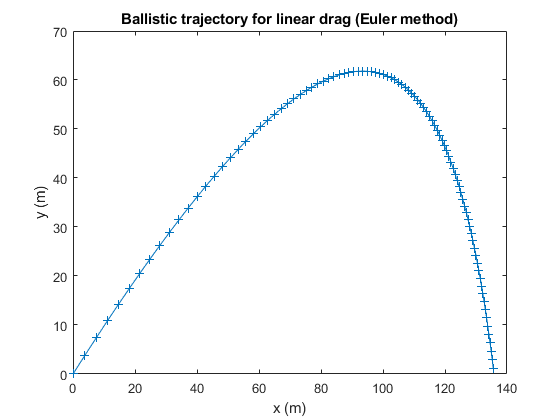

plot(x,z,'+-')
xlabel('x (m)');ylabel('y (m)');
title('Ballistic trajectory for linear drag (Euler method)')

Plot vertical position, velocity, and acceleration versus time including a symbol so we can see the time steps.

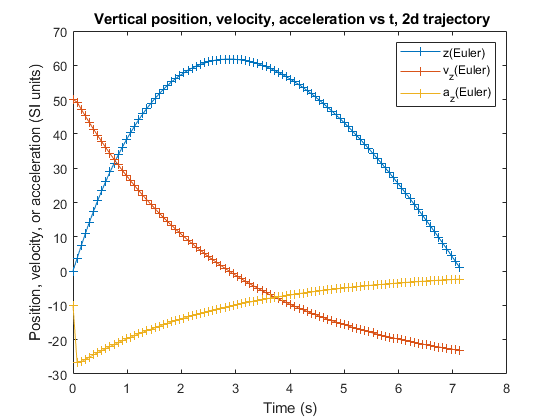

figure
plot(t,z,'+-')
xlabel('Time (s)')
ylabel('Position, velocity, or acceleration (SI units)')
hold on
plot(t,vz,'+-')
plot(t,az,'+-')
title(' Vertical position, velocity, acceleration vs t, 2d trajectory')
legend('z(Euler)','v_z(Euler)','a_z(Euler)')

We observe the vertical acceleration approaching zero from below, the vertical velocity approaching a downwards terminal velocity, and that the vertical displacement is not a quadratic function of time when drag is significant.

**Try this**: Duplicate the above plot for the horizontal x-components if you want to.

## Symbolic analytic solutions

For each component of velocity, the analytic solution can be found by integrating both sides of the expression for acceleration component again thusly:


$${dv_x\over dt} = g_x-v/\tau \rightarrow \int {dv_x\over (g_x-v_x/\tau)}=\int dt \rightarrow \ln {{g_x-v_x(t)/\tau}\over {g_x-v_{x0}/\tau}}=t\rightarrow  v_x(t) = g_x \tau (1-e^{-t/\tau}) - v_{x0}e^{-t/\tau})$$


with a similar expression for the $z$-component. The vector velocity approaches terminal vector velocity $g\tau$ exponentially (first term) while the dependence on the initial vectorvelocity $v_0$ is erased exponentially (2nd term). To perform this integration symbolically in MATLAB for say the $z$-component, we simply repeat the steps in the 1d-motion case.

syms Z(T) V(T) TAU G V0 Z0

We declare a first order differential equation $dv/dt = g-v/\tau$ we will call `ode` thusly:

ode = diff(V,T)==G - V/TAU;

We declare a constraint called `cond`, that the initial velocity is a prenamed symbolic variable. Otherwise the solution will have an equivalent arbitrary constant of integration called something opaque like "C2".  Comment out the following line and remove the "`,cond`" in the argument of `dsolve `below to verify this.

cond = V(0) == V0;

The following function call creates a function we have simply called `vSoultion`(T) (pick any convenient name) which is the symbolic solution for velocity. Since there is no semicolon, after the call, MATLAB will print out the function. 

vSolution(T) = dsolve(ode,cond)

$$vSolution(T) = {\mathrm{e}}^{-\frac{T}{\mathrm{TAU}}}\,\left(V_{0}-G\,\mathrm{TAU}\right)+G\,\mathrm{TAU}$$

Since position is related to velocity by  $dz/dt = v(t)$, we can integrate again analytically by hand (or use dsolve) to get position versus time:

$z(t) =  z_0 + \tau (v_0 - g\tau) + gt\tau -\tau e^{-t/\tau}(v_0 - g\tau)$.

Let's go ahead and try it with MATLABs symbolic solution methods.

ode = diff(Z,T)==vSolution(T)

$$ode(T) = \frac{\partial }{\partial T}Z\left(T\right)={\mathrm{e}}^{-\frac{T}{\mathrm{TAU}}}\,\left(V_{0}-G\,\mathrm{TAU}\right)+G\,\mathrm{TAU}$$

Constrain initial position now. Note, z0 was declared to be a symbolic variable above.

cond = Z(0) == Z0 

$$cond = Z\left(0\right)=Z_{0}$$

zSolution(T) = dsolve(ode, cond)

$$zSolution(T) = Z_{0}+\mathrm{TAU}\,\left(V_{0}-G\,\mathrm{TAU}\right)-\mathrm{TAU}\,{\mathrm{e}}^{-\frac{T}{\mathrm{TAU}}}\,\left(V_{0}-G\,\mathrm{TAU}\right)+G\,T\,\mathrm{TAU}$$

Let's compute the values of the exact solutions. First substitute the numerical value of initial velocity v0 for the symbolic variable V0 into the symbolic function to get a new function vS. We do this for the $z$-component to illustrate.

vS= subs(vSolution, V0, vz0)

$$vS(T) = G\,\mathrm{TAU}-{\mathrm{e}}^{-\frac{T}{\mathrm{TAU}}}\,\left(G\,\mathrm{TAU}-50\right)$$

and subs the numerical initial position z0 for the symbolic variable Z0 and so on (note we need `gz` here), so our final vS depends only on symbolic time.

vS= subs(vS, Z0, z0);vS= subs(vS, TAU, tau);vS= subs(vS, G, gz)

$$vS(T) = 80\,{\mathrm{e}}^{-\frac{T}{3}}-30$$

Superpose the exact solution for velocity on the plot generated above via numerical methods, using blue circles.

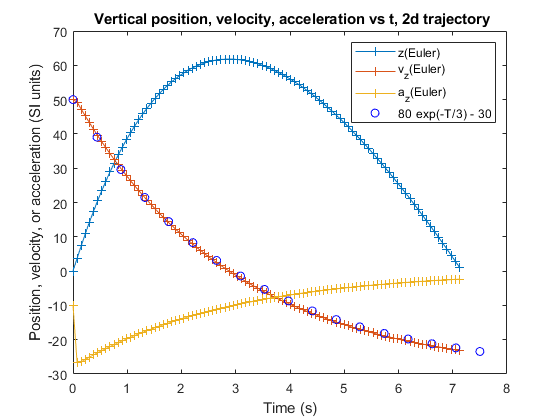

fplot(vS, [tmin tmax],'ob')

Open this plot in a new window and zoom in to examine differences between the exact and the numerical results for the velocity over time. Decrease the time interval to improve the agreement.

Add here code to superpose the exact solutions for position and for acceleration on the plot if you would like.

%%%%%

## ode45 for a 2 dimensional ballistic motion with drag

The next call uses the acceleration function and ode45 to integrate vector acceleration to find vector velocity. The acceleration function must be generalized to accept and return vectors not scalars. We are solving two 1st order ordinary differential equations to find the two velocity vector components over time only. In this first example, we are not integrating velocity to find position simultaneously, just the two components of velocity. (See mass on spring example for how to integrate to obtain velocity and position.)

The 1st argument is the function to integrate, the second the range for its independent variable, and the 3rd the initial values of the arguments of the function,  the dependent variables in the system of now 2 ODEs. (See function below.) To set integration tolerance, use `odeset`. We pass ode45 a handle to our function defining the problem, the time range, and the initial values. Note the @ required handle creation operator and that ode45 returns the independent variable t=time and dependent variable array V in that order and the function must respect this too. Even if the function were a constant and didn't use the dependent variable it must pretend it will.  We get a vector of times and an array of velocity components over time with the call: 

[Tode, Vode]=ode45(@V_t,[tmin,tmax],[vx0,vz0,x0,z0]); 

**Try this**: Take a look at `Vode` in the workspace. It is an array contaiing the values for both velocity components as functions of time.

Compare velocity components for the Euler method, the more accuracte ode45, and the exact result.

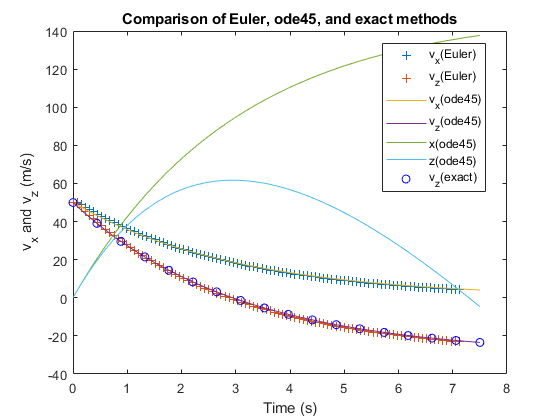

figure
plot(t,vx,'+'); hold on
plot(t,vz,'+')
plot(Tode,Vode)
fplot(vS, [tmin tmax],'ob')
hold off
xlabel ('Time (s)');ylabel('v_x and v_z (m/s)');
title('Comparison of Euler, ode45, and exact methods')
legend('v_x(Euler)','v_z(Euler)',...
    'v_x(ode45)','v_z(ode45)','x(ode45)','z(ode45)','v_z(exact)','Location','best')

### ode45 with event location

The [ODE Event Location](https://www.mathworks.com/help/matlab/math/ode-event-location.html) allows one to check for events within a `ode45` calculation. We use `odeset` to pass a function handle to ode45. The function (see below) terminates ode45 when the condition that z goes below zero from above is met. We then catch additional information, the times te, the values ye, and indices ie of events satisfying the event location conditions.

options=odeset('Events',@bounceEvents,'Refine',10);
[Tode, Vode,te,ye,ie]=ode45(@V_t,[tmin,tmax],[vx0,vz0,x0,z0],options);

Plot ode45 trajectory and add a circle indicating the location of the event which terminated ode45.

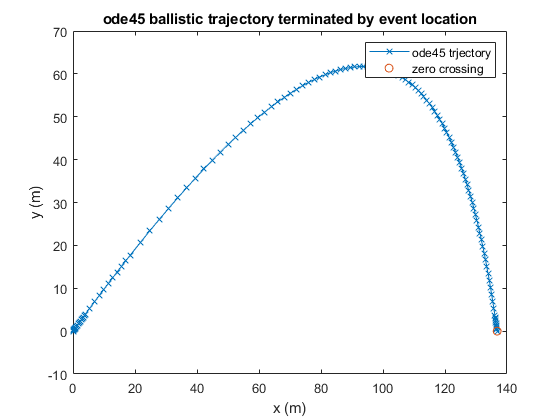

figure
plot(Vode(:,3),Vode(:,4),'x-')
hold on
plot(ye(3),ye(4),'o')
hold off
xlabel('x (m)');ylabel('y (m)');title('ode45 ballistic trajectory terminated by event location')
legend('ode45 trjectory','zero crossing')

## ode45 for a mass on a spring with drag in 2d

We now generalize to include a position dependent force. We are solving four 1st order ordinary differential equations to find two velocity vector components and two position coordinates over time.

Declare a spring natural frequency global variable and initialize it.

global omega
omega=1;

Declare another time constant to characterize the mass on a spring damping time and initialize it.

global tau2;tau2=3;

Initialize velocity and position.

vx0=2.0;vz0=1;x0=0;z0=1.0;

Choose a range of time.

tmin = 0; tmax = 50;

We now call ode45. The 1st argument is the function to integrate, the second the range for its independent variable, and the 3rd the initial values of the arguments of the function,  the dependent variables in the system of now 4 ODEs. (See function below.) 

**Important note**:   In this example we integrate $d{\bf x}/dt = {\bf v}$ and $d{\bf v}/dt = {\bf F}({\bf x},{\bf v})/m$ in a case where the force depends upon the position coordinates. The function V_t2 computes the rates of change of all components.

We get an array of values over time with the call: 

[Tode, VodeHO]=ode45(@V_t2,[tmin tmax],[vx0,vz0, x0,z0]); 

Note that VodeHO contains velocity and position coordinates as functions of time.

Plot position and velocity components as functions of time.

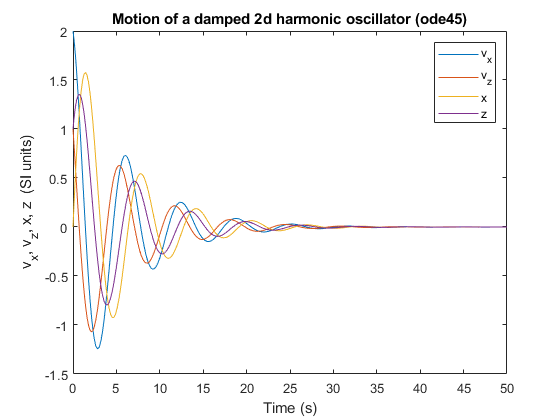

figure
plot(Tode,VodeHO)
xlabel ('Time (s)');ylabel('v_x, v_z, x, z  (SI units)');
title('Motion of a damped 2d harmonic oscillator (ode45)')
legend('v_x','v_z','x','z')

Use [quiver](https://www.mathworks.com/help/matlab/ref/quiver.html) to plot orbit as arrows.

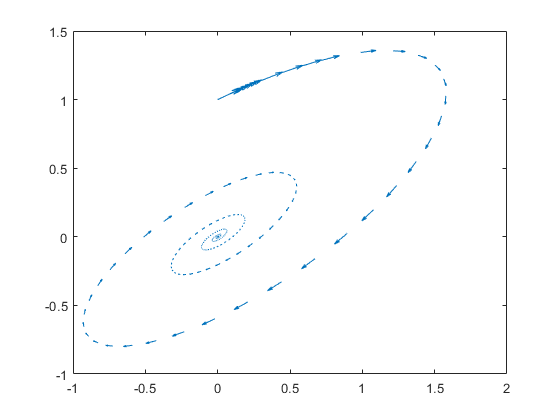

figure
quiver(VodeHO(:,3),VodeHO(:,4),VodeHO(:,1),VodeHO(:,2))
hold on

We observe an elliptical orbit centered on the origin decaying in amplitude over time as a result of energy loss to the drag force.

**Try this**: Play with initial conditions and values for the parameters $\omega$ and $\tau$.

## ode45 with parameters

Instead of using global variables, we can pass to ode45 the expression @(t,V) V_t3(t,V,tau2,omega) which creates a function handle to a new function (see below) with the parameter values hard-wired in.

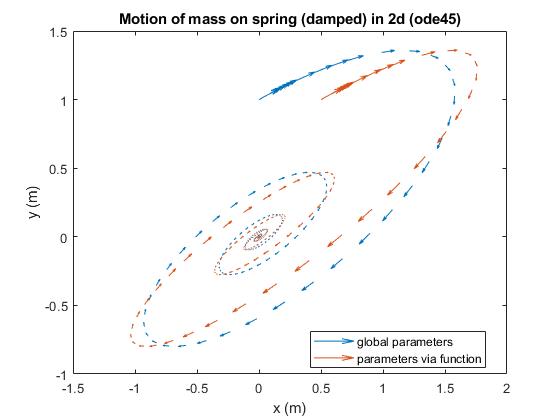

tau3=tau2;omega3=omega;x0=.5;
[Tode, VodeHO2]=ode45(@(t,V) V_t3(t,V,tau3,omega3),[tmin,tmax],[vx0,vz0,x0,z0]); 
quiver(VodeHO2(:,3),VodeHO2(:,4),VodeHO2(:,1),VodeHO2(:,2))
title('Motion of mass on spring (damped) in 2d (ode45)')
xlabel('x (m)');ylabel('y (m)')
legend('global parameters','parameters via function','Location','best')

**Appendix 1**

Here is our 2d acceleration function for ballistics with a drag force linear in velocity. It must be placed at the end of the Live Script  or placed as a separate file in the MATLAB path with the filename equal to the name of the function (e.g. V_t.m) where MATLAB can find it by filename. It accepts a time  and a vector `V` of values of velocity at that time and returns the vector component rates of change as a vector locally (within the function) called `a`. The first input argument (time) is not used so is replaced with a tidle.

function a=V_t(~,V)
    global gx; % acceleration of gravity in m-s^-2
    global gz; % acceleration of gravity in m-s^-2
    global tau; %drag time in s
    vx=V(1);
    vz=V(2);
    ax = gx- (vx/tau);
    az = gz- (vz/tau);

Return rates of change of velocity.

    a=[ax;az;vx;vz];
end

**Appendix 2**: 

To calculate the motion of a mass subject to a position dependent force such as a spring force with ode45, possibly with an external time dependent driving force, we use  `V_t2`  to calculate rates of change of both position and velocity components. We pass any needed parameters as initialized global variables. We include position and velocity in the input vector V, compute rates of change of all components of V,and return all the rates of change. Call `ode45` with the new function specifying a time interval and a vector of initial values for all position and velocity components. Since we do not use the time variable in the function, we replace the input argument with a tidle.

function Vdot=V_t2(~,V)
    global tau2; %drag time in s
    global omega; % spring natural frequency
    vx=V(1);vz=V(2);
    x=V(3);z=V(4);
    ax = -omega^2*x- (vx/tau2);
    az = -omega^2*z - (vz/tau2);
    Vdot=[ax;az;vx;vz];
end

**Appendix 3:**

The following function is used to terminate `ode45` calculation of a ballistic motion. 

function [value,isterminal,direction] = bounceEvents(t,y)
    value = y(4);     % Detect height = 0
    isterminal = 1;   % Stop the integration
    direction = -1;   % Terminate if negative direction
end

**Appendix 4**: 

This ode function describes a 2d damped harmonic oscillator with decay time and natural frequency passed as parameters.

function Vdot=V_t3(~,V,tau,omega)
%    tau; %drag time in s
%    omega; % spring natural frequency
    vx=V(1);vz=V(2);
    x=V(3);z=V(4);
    ax = -omega^2*x- (vx/tau);
    az = -omega^2*z - (vz/tau);
    Vdot=[ax;az;vx;vz];
end

## End of script